# fMRI data analysis tutorial for COCOAN101-L04

by Choong-Wan (Wani) Woo

## Agenda

## 1. Introducing canlab tools

- [https://canlab.github.io/](https://canlab.github.io/)

- some important objects: fmri_data (and image_vector), region, statistic_image, fmridisplay, atlas 

- cf. [https://canlab.github.io/objectoriented/](https://canlab.github.io/objectoriented/)

## 2. Install! 

- [https://github.com/canlab](https://github.com/canlab)

- [https://github.com/canlab/CanlabCore](https://github.com/canlab/CanlabCore)

- cf. [https://canlab.github.io/setup/](https://canlab.github.io/setup/)

## 3. Getting example dataset

- [https://www.dropbox.com/sh/7yqf9r2ncttkcix/AAAgOAMkGeSWX3PTOhBBaqE9a?dl=0](https://www.dropbox.com/sh/7yqf9r2ncttkcix/AAAgOAMkGeSWX3PTOhBBaqE9a?dl=0)

(End of video 1)

## **4. Load data and basic QC (plot)**

% key functions: fmri_data, plot

basedir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/COCOAN101/L04';
% datdir = fullfile(basedir, 'example_data/bmrk3_temp_avg');
datdir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/R_advancedfmri/advancedfmrianalysis2_2020spring/tutorials/wani_session/example_data/bmrk3_temp_avg';

imgs = filenames(fullfile(datdir, 'sub*heat*nii'));

dat = fmri_data(imgs);

Using default mask: /Users/clinpsywoo/Dropbox/github/canlab/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 187756272 bytes
Loading image number:   198
경과 시간은 3.538869초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


% default mask: >> which('brainmask_canlab.nii')
% or you can also use different masks, e.g., 

dat_gray = fmri_data(imgs, which('gray_matter_mask.nii'));

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 154924704 bytes
Loading image number:   198
경과 시간은 1.888608초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Calculating mahalanobis distances to identify extreme-valued images
...based on union of corr...Retained 15 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 57.58%
Expected 9.90 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 20 60 173 

...and cov...Retained 8 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.71%
Expected 9.90 outside 95% ellipsoid, found  20

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 11 images		Cases 6 24 36 42 60 66 78 90 114 174 198 
Uncorrected: 20 images		Cases 6 11 12 24 36 41 42 54 60 66 78 90 96 102 114 168 174 180 192 198 

done.
Outliers:
Outliers after p-value correction:
Image numbers: 6 24 36 42 60 66 78 90 114 174 198 

Image numbers, uncorrected: 6 11 12 20 24 36 41 42 54 60 66 78 90 96 102 114 168 173 174 180 192 198 
SPM12: spm_

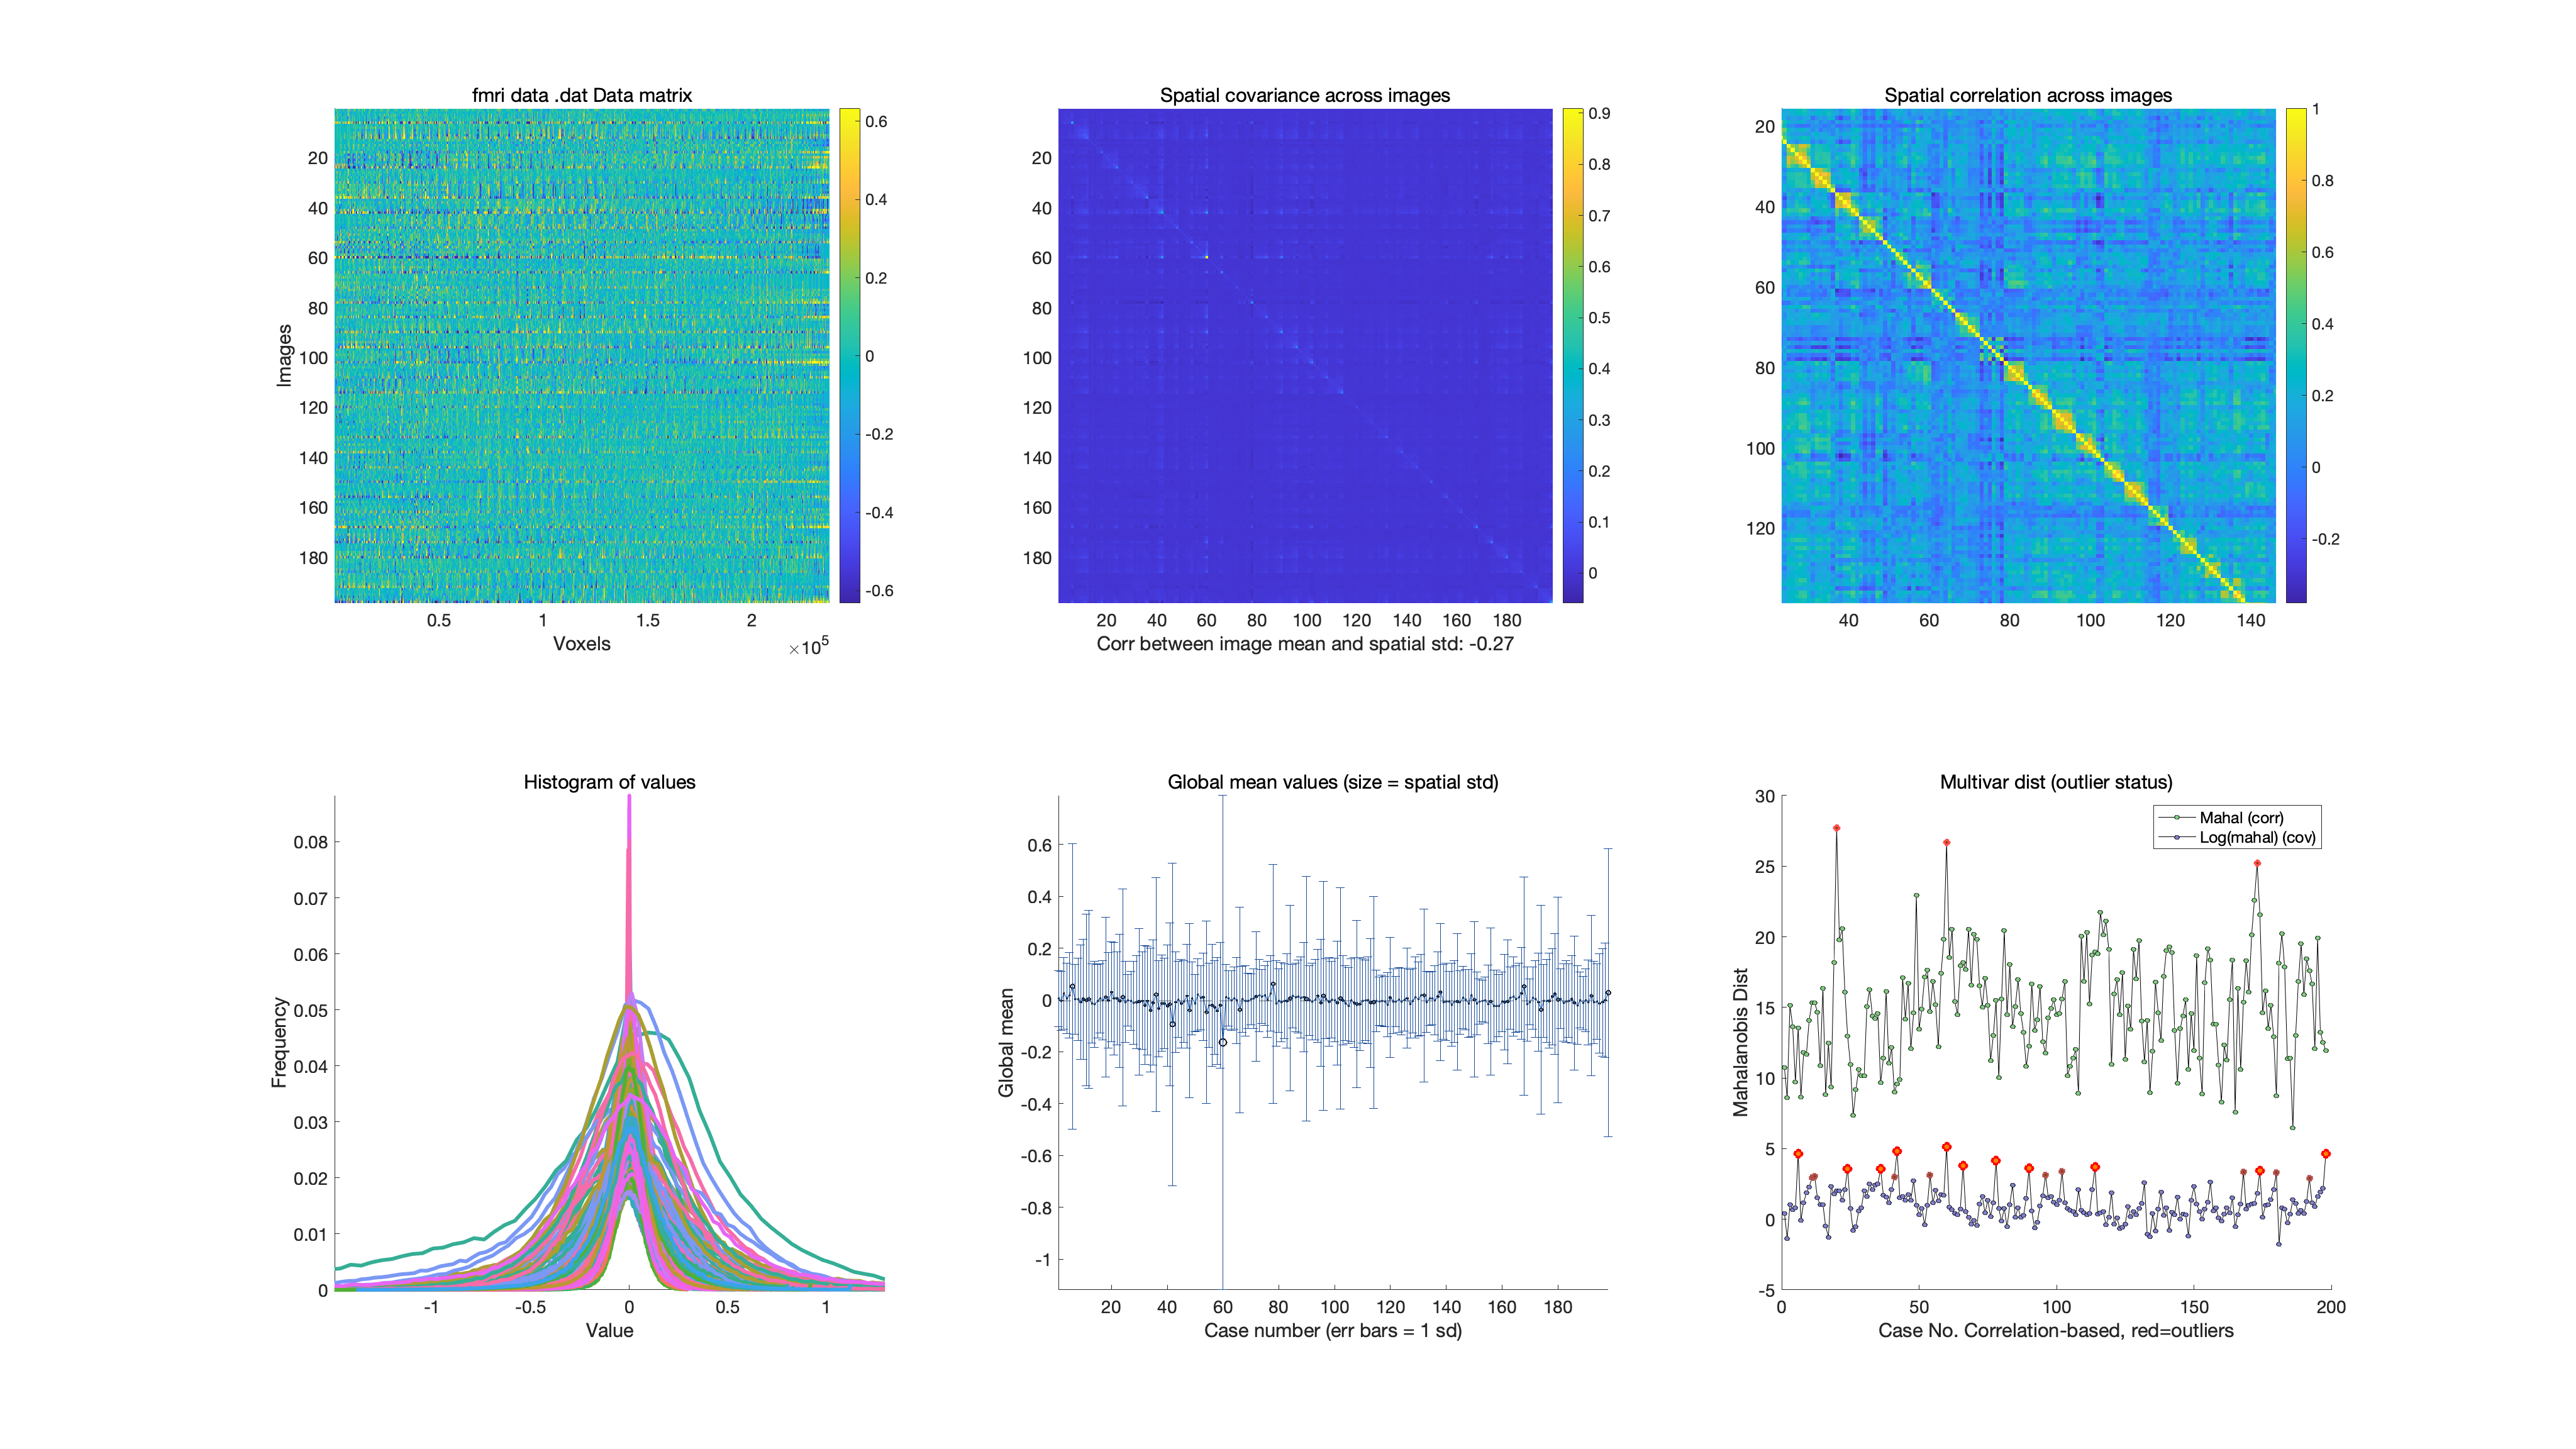

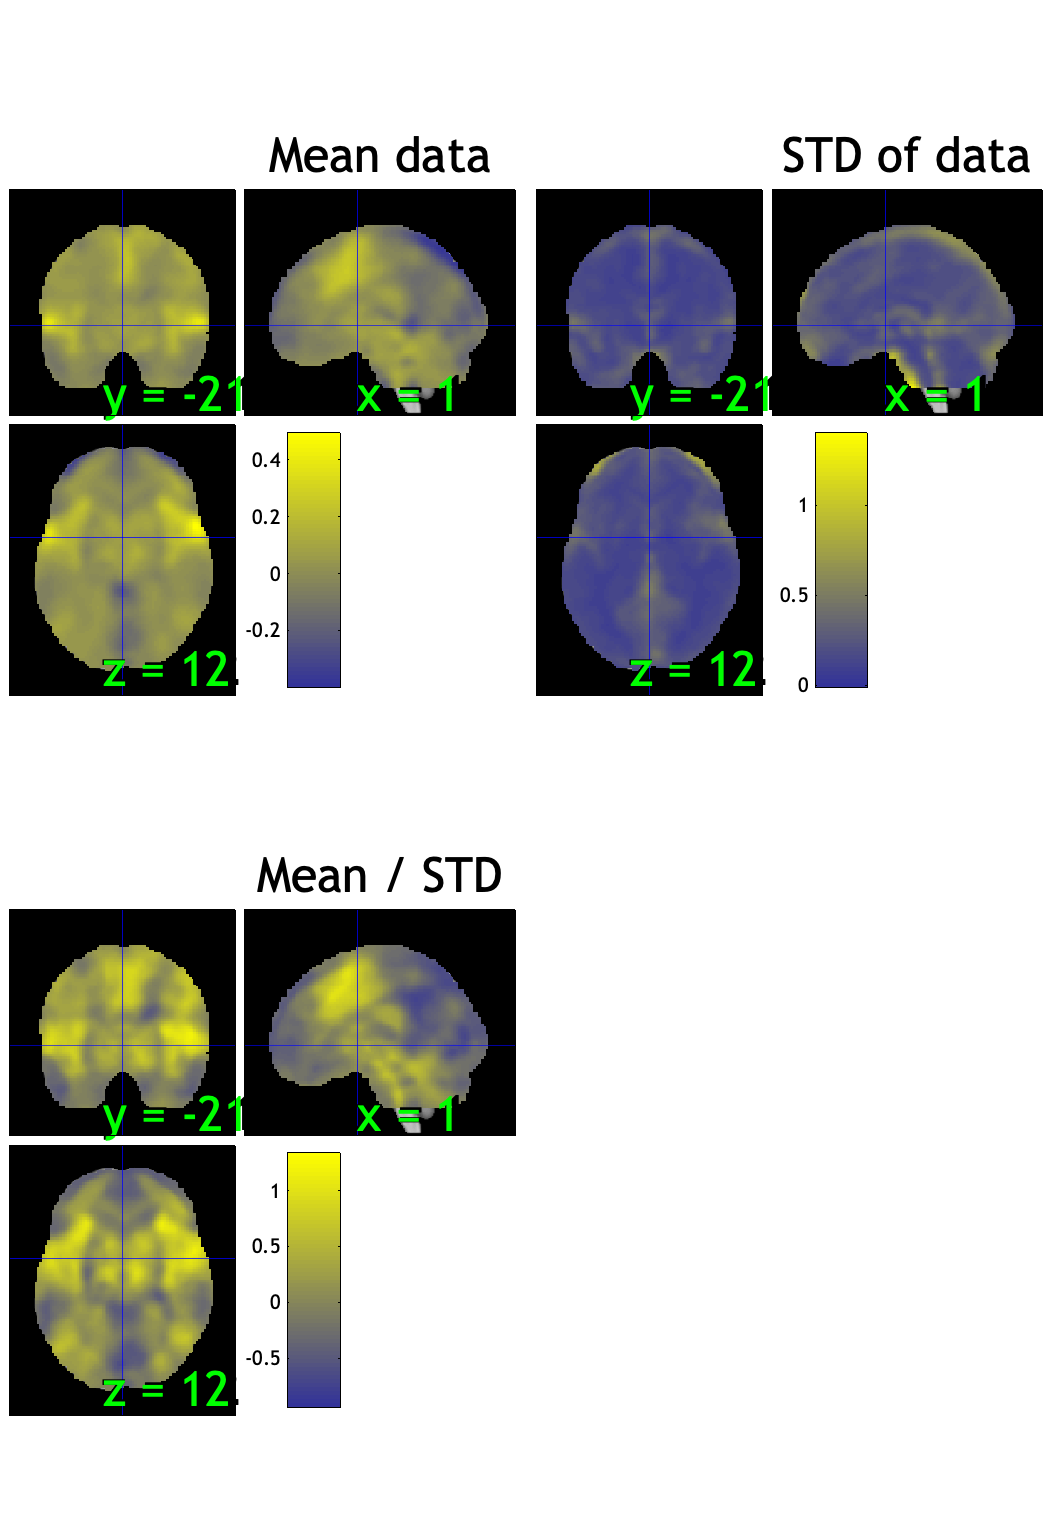

ans = 198×1 logical 배열
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


plot(dat)

plot(dat_gray)

## **5. Mean and one-sample t-test**

% key funtions: mean, ttest

mdat = mean(dat);
% orthviews(mdat);

% tdat = ttest(dat, 0.05, 'unc');
% tdat = ttest(dat, 0.05, 'fdr');
tdat = ttest(dat, 0.05, 'bfr');

One-sample t-test
Calculating t-statistics and p-values

Image   1
 49 contig. clusters, sizes   1 to 13788
Positive effect: 31379 voxels, min p-value: 0.00000000
Negative effect: 23897 voxels, min p-value: 0.00000000


% orthviews(tdat);

## **6. multiple-testing correction and visualize brain maps**

%% key functions: threshold, canlab_results_fmridisplay or
% brain_activations_wani

tdat = threshold(tdat, 0.05, 'unc')


Image   1
 14 contig. clusters, sizes   1 to 158205
Positive effect: 74208 voxels, min p-value: 0.00000000
Negative effect: 85063 voxels, min p-value: 0.00000000


tdat =   statistic_image - 속성 있음:

              type: 'T'
                 p: [237066×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [237066×1 single]
         threshold: 0.0500
          thr_type: []
               sig: [237066×1 logical]
                 N: [237066×1 single]
               dfe: 197
               dat: [237066×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [237066×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'  'removed   0 empty voxels and   0 empty images'}


tdat = threshold(tdat, 0.05, 'fdr')

Image   1 FDR q < 0.050 threshold is 0.032151

Image   1
 18 contig. clusters, sizes   1 to 148919
Positive effect: 71217 voxels, min p-value: 0.00000000
Negative effect: 81225 voxels, min p-value: 0.00000000


tdat =   statistic_image - 속성 있음:

              type: 'T'
                 p: [237066×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [237066×1 single]
         threshold: 0.0322
          thr_type: []
               sig: [237066×1 logical]
                 N: [237066×1 single]
               dfe: 197
               dat: [237066×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [237066×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'  'removed   0 empty voxels and   0 empty images'  'removed   0 empty voxels and   0 empty images'}


tdat = threshold(tdat, 0.05, 'bfr')


Image   1
 49 contig. clusters, sizes   1 to 13788
Positive effect: 31379 voxels, min p-value: 0.00000000
Negative effect: 23897 voxels, min p-value: 0.00000000


tdat =   statistic_image - 속성 있음:

              type: 'T'
                 p: [237066×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [237066×1 single]
         threshold: 2.1091e-07
          thr_type: []
               sig: [237066×1 logical]
                 N: [237066×1 single]
               dfe: 197
               dat: [237066×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [237066×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {1×5 cell}


Grouping contiguous voxels:  49 regions
Setting up fmridisplay objects
sagittal montage: 1305 voxels displayed, 53971 not displayed on these slices
sagittal montage: 1511 voxels displayed, 53765 not displayed on these slices
axial montage: 8132 voxels displayed, 47144 not displayed on these slices
axial montage: 8811 voxels displayed, 46465 not displayed on these slices


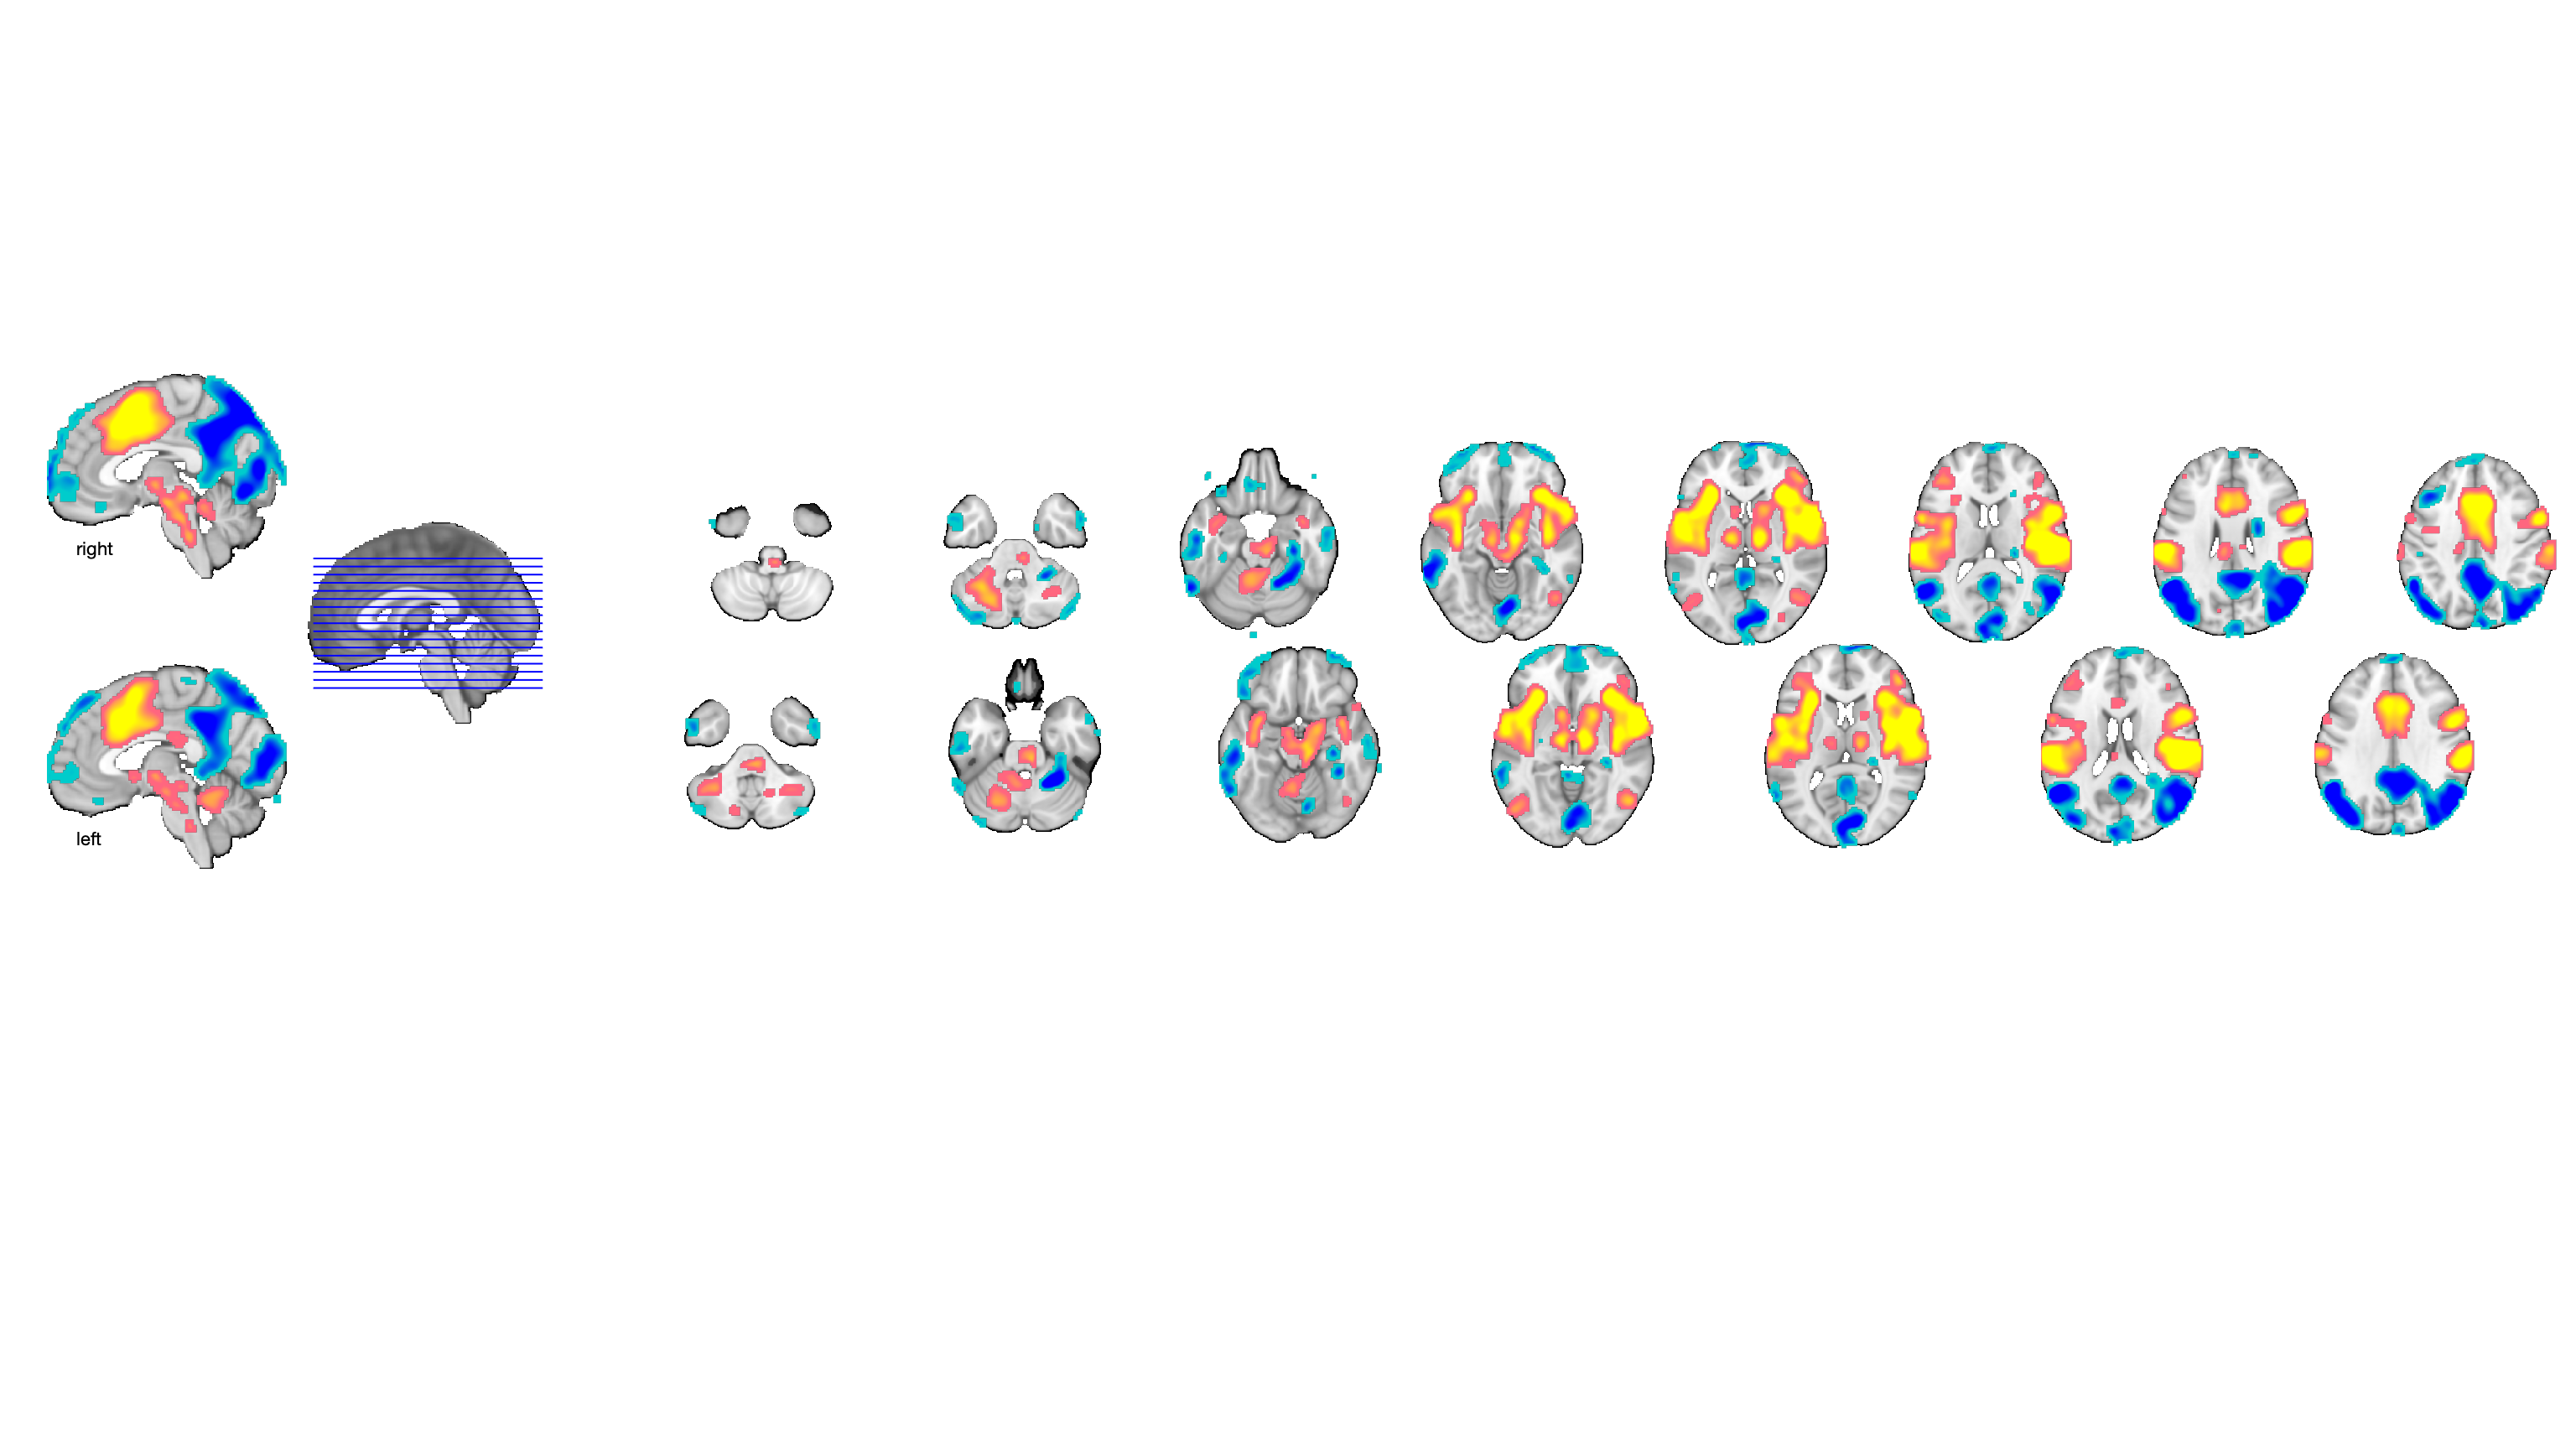

o2 =   fmridisplay - 속성 있음:

            overlay: '/Users/clinpsywoo/Dropbox/github/canlab/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


close all;
o2 = canlab_results_fmridisplay(tdat)

(End of video 3)

## 7. Use Brain_activation_wani in CocoanCORE

Grouping contiguous voxels:  49 regions
Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster
Using custom color maps.
cluster_surf
___________________________________________
	  1 cluster structures entered
  Colors are:
 1  0  0
 Building XYZ coord list
 Getting heat-mapped colors
 Building color change function call
 Loading surface image
 Running color change.
 eval: [c,alld] = getVertexColors(xyz{1},p,mycolors{1},[.5 .5 .5],3,'ovlcolor',[0 1 1],'colorscale',actcolors{1},'fsavg_right');
Main color vertices: 163842 vertices.  selecting: 163842
55276 coords.  selecting: 33237
Running  34 sets of coordinates: 034Finished!
___________________________________________
Cluster_surf uses a type of surface rendering with cluster_surf that is deprecated
It still functions, but the new method based on isocolors is dramatically faster
Using custom color maps.
cluster_surf
_____________

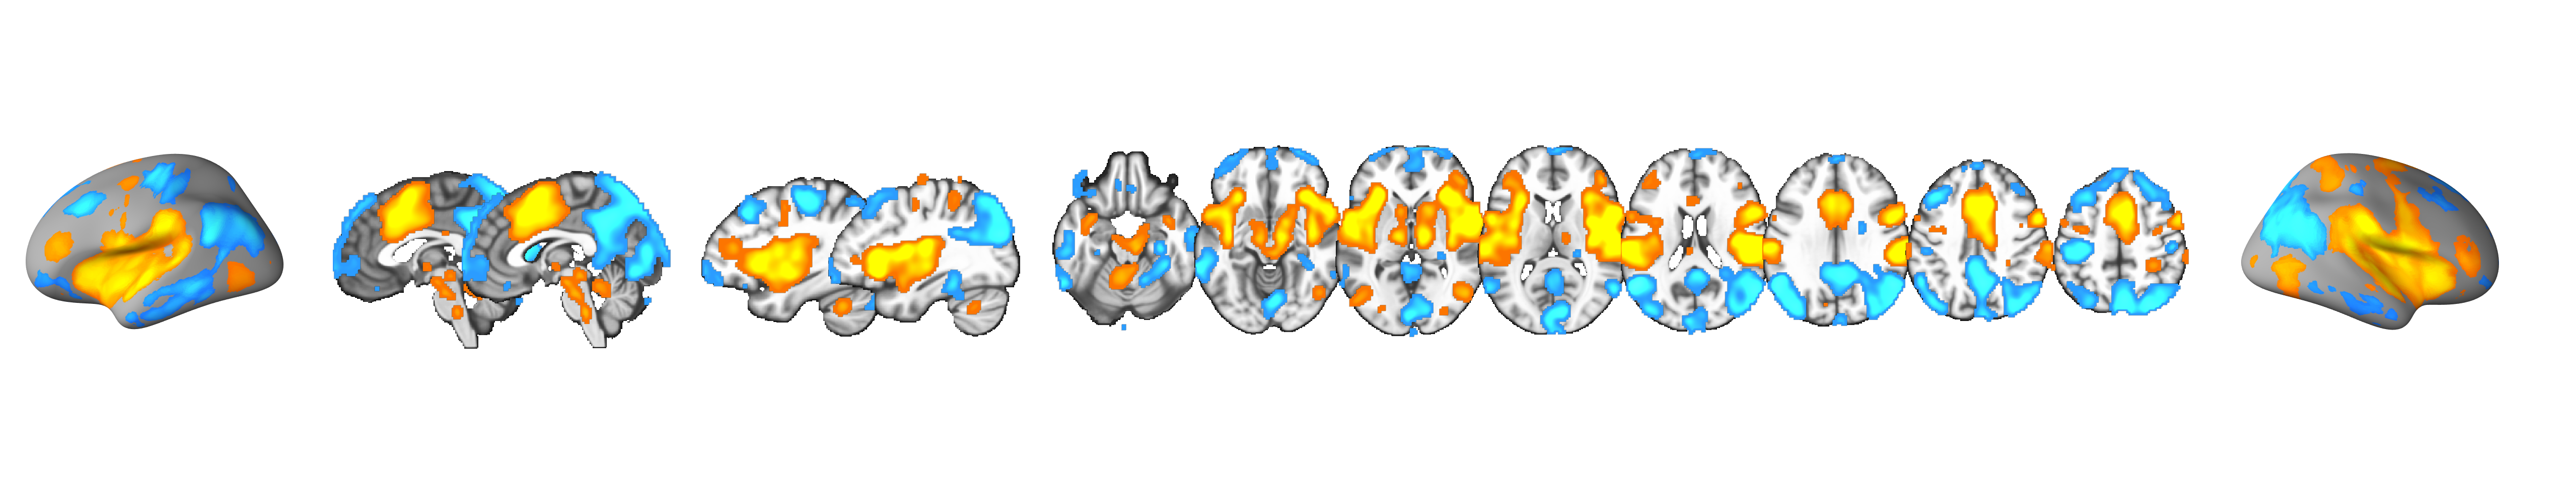

out = 다음 필드를 포함한 struct :
    h_surf_R: [1×1 Patch]
    h_surf_L: [1×1 Patch]


o2 =   fmridisplay - 속성 있음:

            overlay: '/Users/clinpsywoo/Dropbox/github/canlab/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


close all;
% you need this to use brain_activations_wani: https://github.com/cocoanlab/cocoanCORE

[out, o2] = brain_activations_wani(region(tdat))

% useful function: pruning_img

p = [0.00001 0.000001 0.05/size(tdat.dat,1)];
k = [1 1 10]
[dat, r] = pruning_img(tdat, p, k);

[out, o2] = brain_activations_wani(r)



[out, o2] = brain_activations_wani(region(tdat), o2, 'outline')


% writing image
tdat.fullpath = 'temp_avg_bfr.nii';
write(tdat, 'thresh', 'overwrite');



## 8. Making a thalamus mask and reading the data from thalamus for two different temperatures

% mask atlas: CANlab_combined_atlas_object_2018.mat
% key functions: select_atlas_subset, 
% apply_mask or extract_roi_averages

load(which('CANlab_combined_atlas_object_2018.mat'));
thal = select_atlas_subset(atlas_obj, {'Thal'});
nac = select_atlas_subset(atlas_obj, {'NAC'});
amyg = select_atlas_subset(atlas_obj, {'Amygdala'});

thal = remove_empty(thal);
nac = remove_empty(nac);
amyg = remove_empty(amyg);

dat_thal = apply_mask(dat, thal);
dat_nac = apply_mask(dat, nac);
dat_amyg = apply_mask(dat, amyg);


## 9. one-sample t-test and plotting for two different temperatures

% key functions: ttest, plot_specificity_box
temp_idx = repmat((1:6)', 1, 33);
temp_idx = temp_idx(:);

dat_heatlv2 = dat_thal.dat(:, temp_idx==2);
dat_heatlv5 = dat_thal.dat(:, temp_idx==5);

[h, p, ci, tstat] = ttest((mean(dat_heatlv5)-mean(dat_heatlv2))');

out = plot_specificity_box(mean(dat_heatlv5)', mean(dat_heatlv2)');

(End of video 4)

## Bonus 1: Mediation analysis


% mediation
load(fullfile(datdir, 'bmrk3_temp_data_descript.mat'));

x = temp_idx;
m = mean(dat_thal.dat)';
% m = mean(dat_nac.dat)';
y = bmrkdata.ratings';
y = y(:);

[paths, stats] = mediation(x, y, m, 'verbose');

Mediation analysis

Observations: 198, Replications:   1
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Single-level analysis.
Options:
	Plots: No
	Bootstrap: No
	Robust: No
	Logistic(Y): No
 Done.

________________________________________

Single-level model
	a	b	c'	c	ab	
Coeff	-0.01	76.22	23.81	23.08	-0.73	
STE	0.00	21.82	1.25	1.26	0.38	
t (~N)	-2.40	3.49	19.10	18.27	-1.92	
Z	-2.38	3.44	Inf	Inf	-1.91	
p	0.0175	0.0006	0.0000	0.0000	0.0559	

________________________________________
Total time:   0 s


sub_idx = repmat(1:33, 6, 1);
sub_idx = sub_idx(:);

for i = 1:33
    x2{i} = [1:6]';
    m2{i} = mean(dat_thal.dat(:,sub_idx==i))';
    y2{i} = bmrkdata.ratings(i,:)';
    m2_2{i} = mean(dat_amyg.dat(:,sub_idx==i))';
    
    cov2{i} = mean(dat_nac.dat(:,sub_idx==i))';
end

[paths, stats] = mediation(x2, y2, m2, 'verbose');

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	0.01	46.71	21.41	22.01	0.36	
STE	0.00	32.78	1.54	1.33	0.49	
t (~N)	3.09	1.43	13.88	16.52	0.73	
Z	2.87	1.39	8.21	8.21	0.72	
dfe	31.49	28.75	30.14	31.63	23.09	
p	0.0042	0.1649	0.0000	0.0000	0.4742	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x2, y2, m2, 'covs', cov2, 'verbose');

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: Yes,  33 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	0.01	-12.65	22.36	21.40	-0.38	
STE	0.00	42.30	1.89	1.56	0.72	
t (~N)	2.82	-0.30	11.84	13.68	-0.53	
Z	2.64	-0.30	8.21	8.21	-0.53	
dfe	30.92	27.94	31.24	31.61	27.24	
p	0.0082	0.7672	0.0000	0.0000	0.5982	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x2, y2, m2, 'M', m2_2,  'verbose');

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M
Additional mediators: AddM1  

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	a_2	b_2	ab_2	
Coeff	0.01	86.24	20.89	22.01	0.41	0.00	-11.02	0.25	
STE	0.00	33.33	1.66	1.33	0.55	0.00	38.30	0.49	
t (~N)	3.09	2.59	12.59	16.52	0.75	0.56	-0.29	0.52	
Z	2.87	2.42	8.21	8.21	0.73	0.55	-0.28	0.51	
dfe	31.49	26.62	29.33	31.63	18.94	31.62	14.39	27.21	
p	0.0042	0.0155	0.0000	0.0000	0.4652	0.5796	0.7778	0.6087	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x2, y2, m2, 'verbose', 'boot', 'bootsamples', 10000);

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 033 Done.
Bootstrapping 10000 samples...

 Min p-value is 0.000100. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   0 s 

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	0.01	46.71	21.41	22.01	0.36	
STE	0.00	30.01	1.48	0.99	0.33	
t (~N)	3.30	1.56	14.46	22.18	1.09	
Z	3.45	1.57	3.87	3.51	1.16	
p	0.0006	0.1164	0.0001	0.0004	0.2465	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x2, y2, m2, 'covs', cov2, 'verbose', 'boot', 'bootsamples', 10000);

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: Yes,  33 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 033 Done.
Bootstrapping 10000 samples... Min p-value is 0.000100. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   0 s 

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	0.01	-12.64	22.36	21.40	-0.38	
STE	0.00	42.03	1.89	1.33	0.57	
t (~N)	2.92	-0.30	11.80	16.14	-0.67	
Z	3.06	-0.22	3.97	3.75	-0.48	
p	0.0022	0.8221	0.0001	0.0002	0.6284	

________________________________________
Total time:   0 s


[paths, stats] = mediation_threepaths(x2, y2, m2, m2_2, 'covs', cov2, 'verbose', 'boot', 'bootsamples', 10000);

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M1

Covariates: Yes,  33 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Bootstrap: Yes
	Logistic(Y): No
 Done.
Bootstrapping 10000 samples... Min p-value is 0.366400. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   0 s 

________________________________________
Average p-value tolerance (average max alpha): 0.4397

Multi-level model
	b1	b2	b3	c'	c	b1b2b3	
Coeff	0.01	-0.14	-28.09	22.84	21.40	-0.01	
STE	0.00	0.18	43.59	2.66	1.35	0.06	
t (~N)	2.93	-0.82	-0.64	8.59	15.89	-0.25	
Z	3.08	-0.79	-0.70	4.26	3.72	-0.26	
p	0.0021	0.4298	0.4849	0.0000	0.0002	0.7959	

________________________________________
Total time:   0 s


## Bonus 2: Predictive modeling 

% prediction

dat_gray = fmri_data(imgs, which('gray_matter_mask.nii'));

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 154924704 bytes
Loading image number:   198
경과 시간은 1.705651초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


pred_y = bmrkdata.ratings';
dat_gray.Y = pred_y(:);
% dat_gray.Y = temp_idx;

wh_fold = sub_idx;

[cverr, stats, optout] = predict(dat_gray, 'algorithm_name', 'cv_pcr', 'nfolds', wh_fold);

Cross-validated prediction with algorithm cv_pcr,  33 folds

Completed fit for all data in:   0 hours   0 min  2 secs 
Fold 1/33 done in:   0 hours   0 min  2 sec
Fold 2/33 done in:   0 hours   0 min  2 sec
Fold 3/33 done in:   0 hours   0 min  2 sec
Fold 4/33 done in:   0 hours   0 min  2 sec
Fold 5/33 done in:   0 hours   0 min  2 sec
Fold 6/33 done in:   0 hours   0 min  2 sec
Fold 7/33 done in:   0 hours   0 min  2 sec
Fold 8/33 done in:   0 hours   0 min  2 sec
Fold 9/33 done in:   0 hours   0 min  2 sec
Fold 10/33 done in:   0 hours   0 min  2 sec
Fold 11/33 done in:   0 hours   0 min  2 sec
Fold 12/33 done in:   0 hours   0 min  2 sec
Fold 13/33 done in:   0 hours   0 min  2 sec
Fold 14/33 done in:   0 hours   0 min  2 sec
Fold 15/33 done in:   0 hours   0 min  2 sec
Fold 16/33 done in:   0 hours   0 min  2 sec
Fold 17/33 done in:   0 hours   0 min  2 sec
Fold 18/33 done in:   0 hours   0 min  2 sec
Fold 19/33 done in:   0 hours   0 min  2 sec
Fold 20/33 done in:   0 hours   0 m

SPM12: spm_check_registration (v6245)              11:51:05 - 19/03/2021
Display /Users/clinpsywoo/Dropbox/github/canlab/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


다음 사용 중 오류가 발생함: matlab.graphics.axis.Axes/set
UIContextMenu의 부모 Figure가 이 객체의 부모 Figure와 동일하지 않습니다.

오류 발생: spm_orthviews>addcontext (1757번 라인)
    set(st.vols{volhandle}.ax{i}.ax,'UIcontextmenu',item_parent);

오류 발생: spm_orthviews>addcontexts (

close all;
orthviews(stats.weight_obj)

(End of video 5)